Constants

clearvars;
num_symbols = 8*1024; 
symbol_rate = 32e9;
time_step = 1/symbol_rate;
upsampling = 2;
sample_rate = upsampling*symbol_rate;
num_samples = upsampling*num_symbols;
Ts = 1/sample_rate;

symbols_q = randi([0 3],1,num_symbols);

Modulation & Upsampling

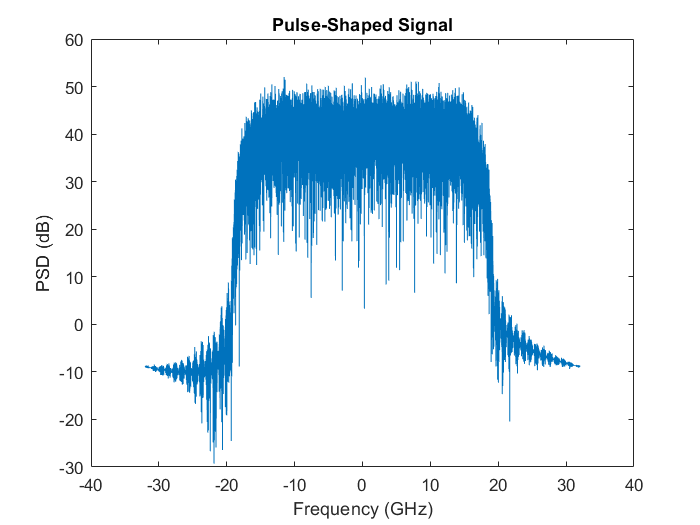

%QPSK
qpsk_mod = pskmod(symbols_q,4,pi/4,'gray');

UPS_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",32,"OutputSamplesPerSymbol",upsampling);
DPS_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",32,"InputSamplesPerSymbol",upsampling,"DecimationFactor",upsampling/2);

upsampled_qpsk = UPS_filter(qpsk_mod.').';

Pxx = ifftshift(fft(upsampled_qpsk).*conj(fft(upsampled_qpsk)));
[~,f] = periodogram(upsampled_qpsk,[],[],sample_rate,'centered');
plot(f/1e9,10*log10(Pxx));
xlabel("Frequency (GHz)");
ylabel("PSD (dB)");
title("Pulse-Shaped Signal")

% matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate,"NumInputPorts",2,"ChannelNames",{"BPSK","QPSK"},"ShowLegend",true);
% raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',sample_rate,"NumInputPorts",2,"ChannelNames",{"BPSK","QPSK"},"ShowLegend",true);
% 
% matched_scope(bpsk_mod',qpsk_mod');
% raised_cosine_scope(upsampled_bpsk',upsampled_qpsk');

Phase Noise

linewidth = 0;
variance = 2*pi*linewidth*Ts;    
phase_noise = randn(1,num_samples);
    
random_walk_phase_noise = cumsum(sqrt(variance)*phase_noise);
          
noisy_qpsk = upsampled_qpsk.*exp(1j*random_walk_phase_noise);

Chromatic Dispersion

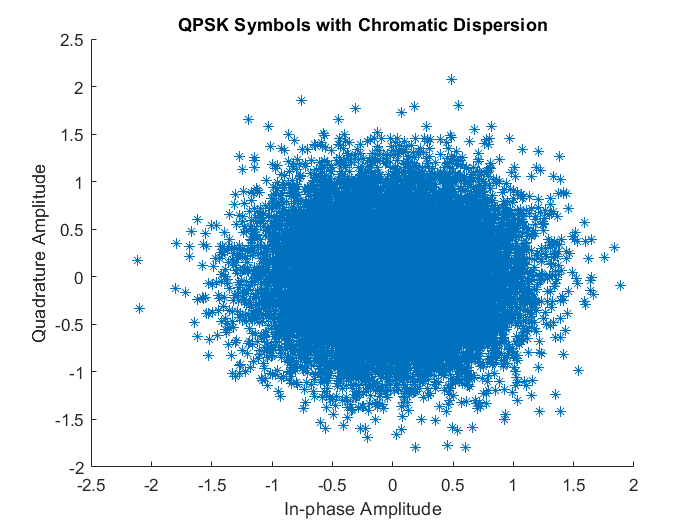

%Define angular frequency vector
 
f_up = (0:(num_samples)/2-1);
f_down = (-(num_samples)/2:-1);
fs = [f_up f_down]*sample_rate/num_samples;
w = 2*pi*fs;
 
%Define Chromatic Dispersion Typical Parameters
z = 1000e3; % m
D = 16*10^-6; % s/m/m
lambda = 1550*10^-9; % m
c = 299792458; % m/s
beta_2 = -lambda*lambda*D/(2*pi*c);

chromatic_dispersion_FIR = exp(-1j*beta_2/2*(w.^2)*z);

CD_qpsk = ifft(chromatic_dispersion_FIR.*fft(upsampled_qpsk)); 


figure
scatter(real(CD_qpsk),imag(CD_qpsk),'*');
title("QPSK Symbols with Chromatic Dispersion");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");

Adaptive Equalisation (Attempt CMA algorithm)

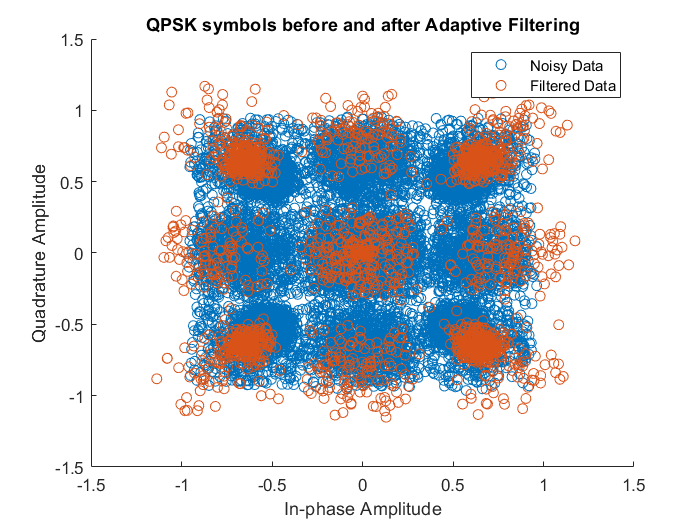

x = noisy_qpsk.'; %Received Input

h_taps = 17; %Small Value, power of 2

h = zeros(h_taps,1);
e = zeros(h_taps,1);
y = zeros('like',x);

h(9) = 1;  
% Train symbols to get h
training_size = 2000;
mu = 0.002;

for i = h_taps:training_size
    
    temp = x(i:-1:i-h_taps+1) ; %From 8th down to 1st
    
    y(i) = h.' * temp;
    
    e(i) = 1 - abs(y(i))^2;
    
    
    h = h + 2*mu*e(i)*conj(temp)*y(i);
end    

figure
hold on
scatter(real(noisy_qpsk),imag(noisy_qpsk));
scatter(real(y),imag(y));
legend("Noisy Data","Filtered Data");
title("QPSK symbols before and after Adaptive Filtering");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

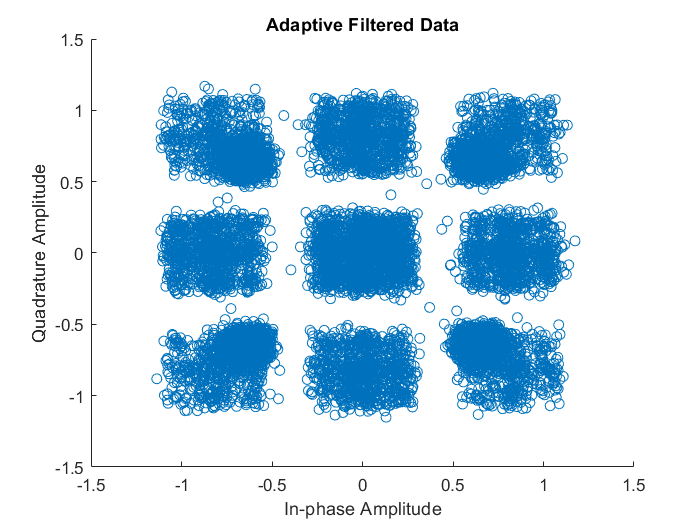


for i =  training_size+1 : num_samples
    
	temp = x(i:-1:i-h_taps+1) ;
    
    y(i) = h' * temp ;
    
    e(i) = 1 - abs(y(i))^2;
end


figure
scatter(real(y),imag(y));
title("Adaptive Filtered Data");
ylabel("Quadrature Amplitude");
xlabel("In-phase Amplitude");

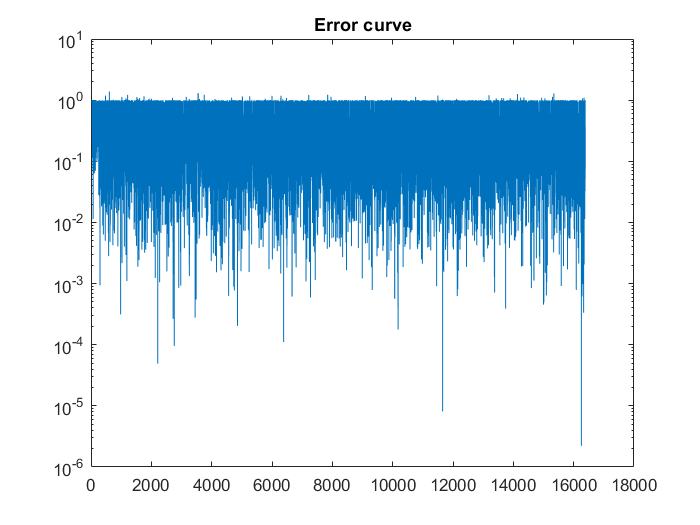


figure
semilogy((abs(e))) ;
title('Error curve');

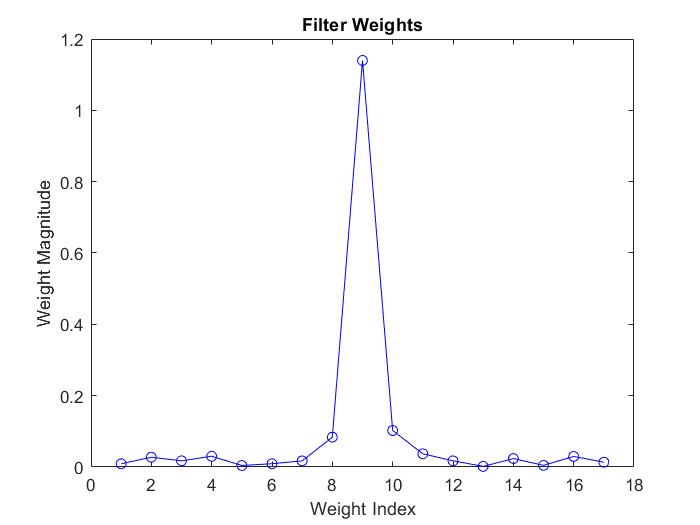


figure
plot(abs(h),'bo-');
title("Filter Weights");
xlabel("Weight Index");
ylabel("Weight Magnitude");



downsampled_qpsk = DPS_filter(y.').';

if mean(abs(downsampled_qpsk(2:2:end)).^2)>mean(abs(downsampled_qpsk(1:2:end)).^2)
   downsampled_qpsk=downsampled_qpsk(2:2:end);
else
   downsampled_qpsk=downsampled_qpsk(1:2:end);
end
    
demoded_qpsk = pskdemod(downsampled_qpsk,4,pi/4,'gray');

lag = finddelay(symbols_q,demoded_qpsk);
[ERRORS,BER] = biterr(symbols_q(1:end-lag),demoded_qpsk(1+lag:end))

ERRORS = 0

BER = 0